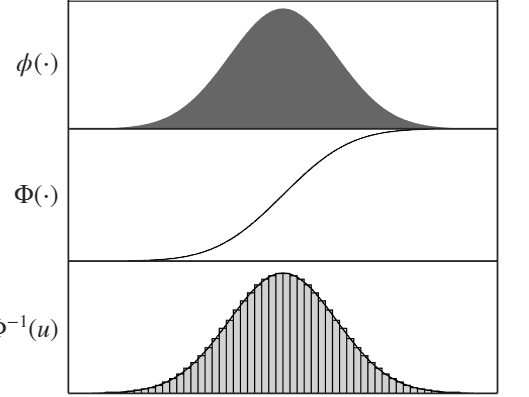

z = linspace(-4, 4, 1000)';
pdf_vals = normpdf(z, 0, 1);
cdf_vals = normcdf(z, 0, 1);

N = 2000;
u = linspace(0, 1, N+2)';
u = u(2:end-1);
z_samples = norminv(u, 0, 1);

figure('Position', [100 100 600 450]);

% PDF 
subplot(3,1,1)
area(z, pdf_vals, 'FaceColor', [0.4 0.4 0.4], 'EdgeColor', 'none');
ylabel('$\phi(\cdot)$','Interpreter','latex','FontSize',18,'Rotation',0,'HorizontalAlignment','right','VerticalAlignment','middle');
set(gca,'XTick',[],'YTick',[],'Box','on','LineWidth',1.2,'FontSize',16)
ylim([0 max(pdf_vals)*1.1])

% CDF 
subplot(3,1,2)
plot(z, cdf_vals, 'k', 'LineWidth', 1);
ylabel('$\Phi(\cdot)$','Interpreter','latex','FontSize',18,'Rotation',0,'HorizontalAlignment','right','VerticalAlignment','middle');
set(gca,'XTick',[],'YTick',[],'Box','on','LineWidth',1.2,'FontSize',16)
ylim([0 1])

% Inverse CDF 
subplot(3,1,3)
histogram(z_samples, 50, 'Normalization','pdf', 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k', 'LineWidth',0.8)
hold on
plot(z, pdf_vals, 'k', 'LineWidth', 1)
ylabel('$\Phi^{-1}(u)$','Interpreter','latex','FontSize',18,'Rotation',0,'HorizontalAlignment','right','VerticalAlignment','middle');
set(gca,'YTick',[],'Box','on','LineWidth',1.2,'FontSize',16)
set(gca,'XTick',[],'YTick',[],'Box','on','LineWidth',1.2,'FontSize',16)
ylim([0 max(pdf_vals)*1.1])
set(gcf, 'Color', 'w')

panelHeight = 0.3333;
set(gca, 'Position', [0.13 0.01 0.81 panelHeight]);      
h2 = subplot(3,1,2); set(h2, 'Position', [0.13 0.01+panelHeight 0.81 panelHeight]); % middle
h3 = subplot(3,1,1); set(h3, 'Position', [0.13 0.01+2*panelHeight 0.81 panelHeight]); % top

axes(h3);
hold on
yline(max(pdf_vals)*1.06, 'k-', 'LineWidth', 1);  
hold off

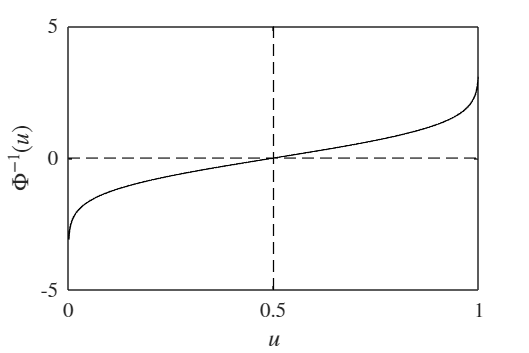



% Inverse Gaussian CDF Plot 
figure('Position', [100 100 600 400])

x = linspace(0, 1, 1000);
y = norminv(x, 0, 1);

plot(x, y, 'k', 'LineWidth', 1); % Black line
hold on

plot([0.5 0.5], [-5 5], 'k--', 'LineWidth', 0.8)
plot([0 1], [0 0], 'k--', 'LineWidth', 0.8)

set(gca, 'FontSize', 14, ...
         'XTick', 0:0.5:1, ...
         'YTick', -5:5:5, ...
         'TickLabelInterpreter', 'latex')

xlabel('$u$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('$\Phi^{-1}(u)$', 'Interpreter', 'latex', 'FontSize', 16)

box on
hold off

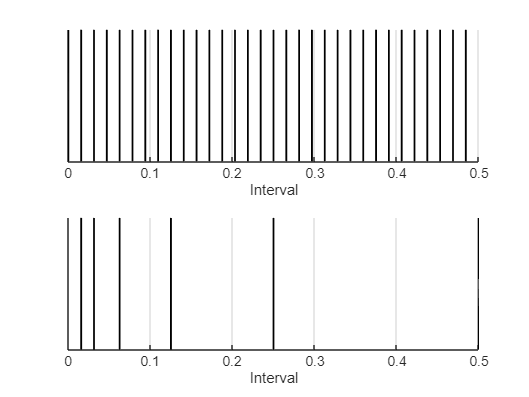





d = 6; 

% Uniform grid points 
j = 0:(2^(d-1)-1);
uniform_points = 2^(-d) * j;

% Dyadic intervals
i = 1:(d-1);
dyadic_intervals_start = 2.^(i-1) .* 2^(-d);
dyadic_intervals_end = 2.^i .* 2^(-d);

yl = [-0.1, 0.1];
x_ticks = 0:0.1:0.5;


figure
subplot(2,1,1)
hold on
for x = uniform_points
    plot([x x], yl, 'k-', 'LineWidth', 1.2)
end
ylim(yl)
xlim([0 0.5])
xticks(x_ticks)
yticks([])
xlabel('Interval')
grid on
hold off

subplot(2,1,2)
hold on
dyadic_points = unique([dyadic_intervals_start, dyadic_intervals_end]);
for x = dyadic_points
    plot([x x], yl, 'k-', 'LineWidth', 1.2)
end
ylim(yl)
xlim([0 0.5])
xticks(x_ticks)
yticks([])
xlabel('Interval')
grid on
hold off